# Lesson 0: Getting to know the problem

An optical engineer your're working with, gives you a phase mask file `phasemask.xlsx`

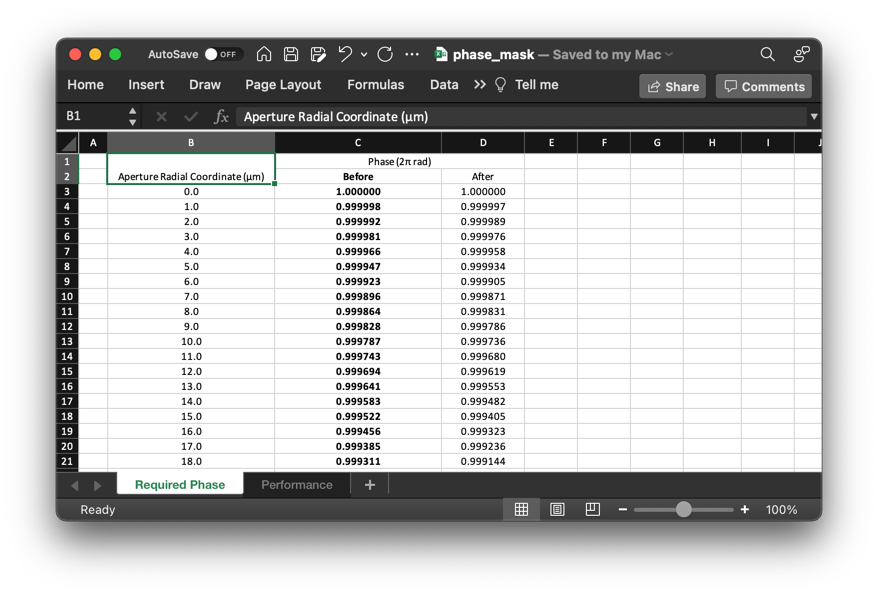

`lesson0.mat` file has the table from the `.xlsx` file as Matlab's matrix (excluding the third column). First, you load it into the workspace:

load('datafiles/lesson0.mat','data');
size(data)

ans =         5001           2


#### Task 1. Make a polar plot of the 'before' data (second column) on a Cartesian grid.

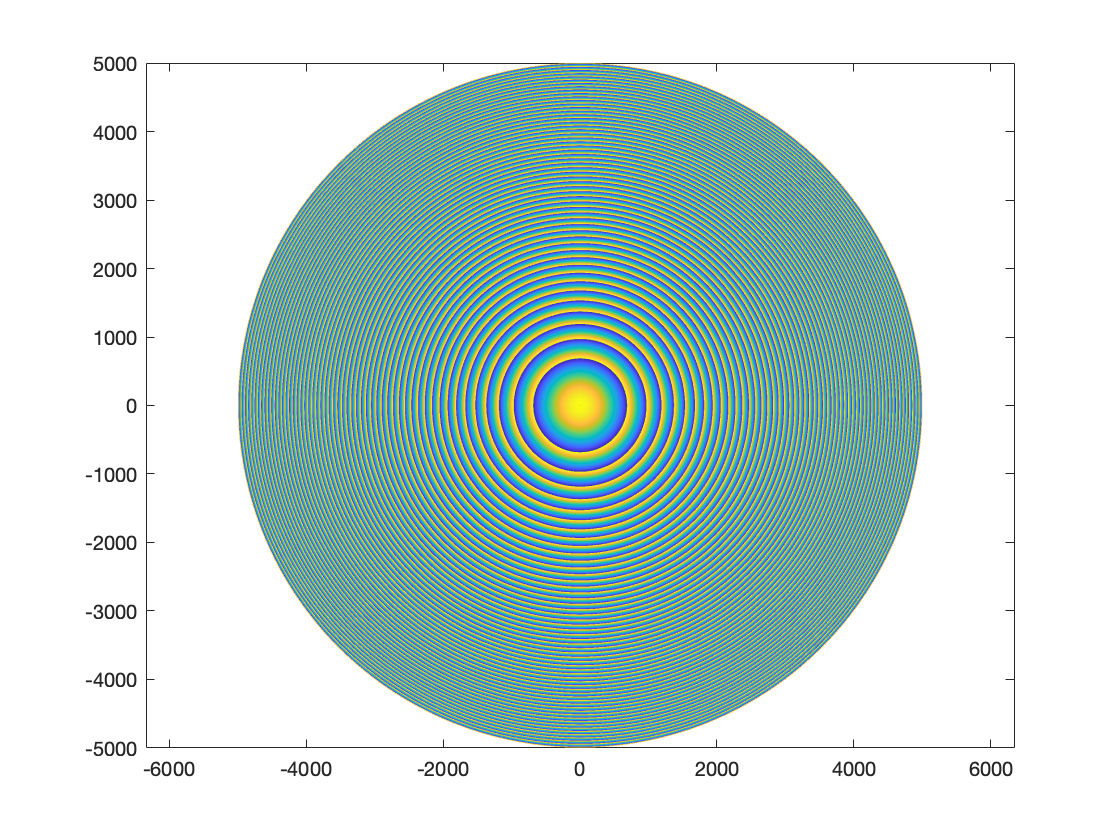

Rmin = data(1,1);
Rmax = data(end,1);
[X, Y] = meshgrid(-Rmax:5:Rmax);
R = sqrt(X.^2 + Y.^2);
map = nan(size(X));
I = R <= Rmax & R >= Rmin;
map(I) = interp1(data(:,1),data(:,2),R(I),'linear');
figure; pcolor(X,Y,mod(map,1)); shading flat; axis equal

Or, using unwrapped data

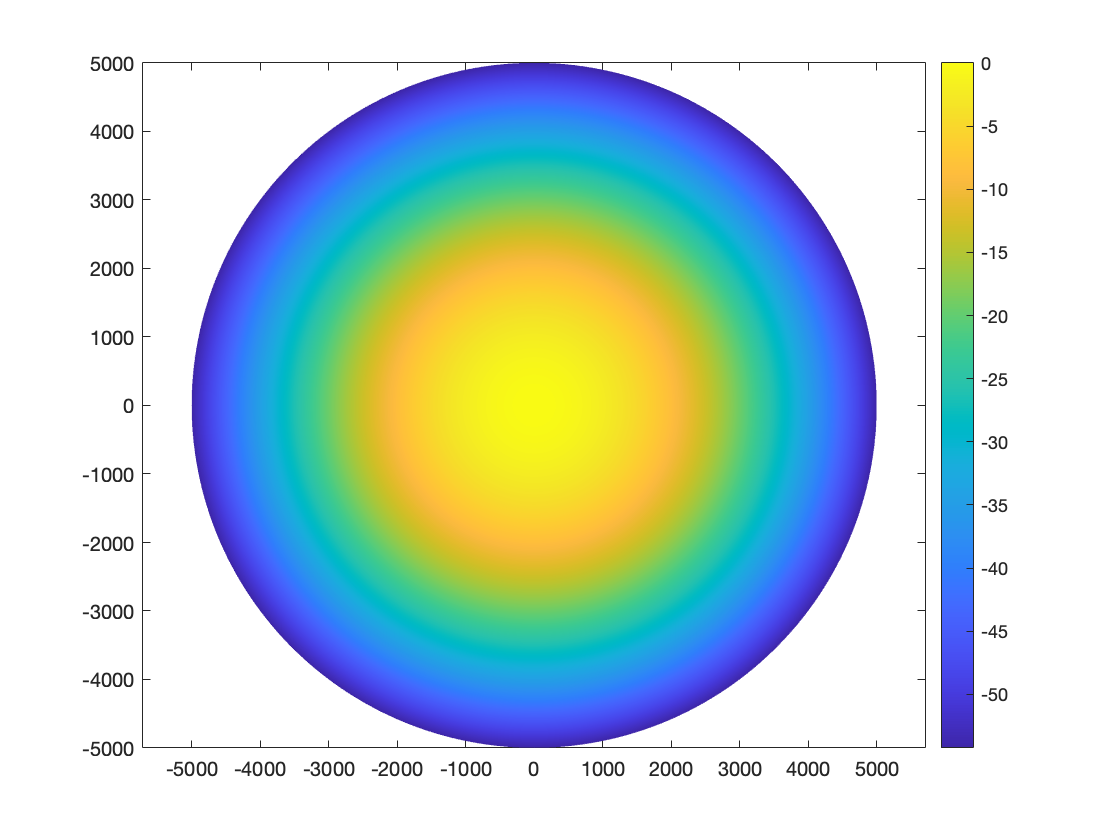

data(:,2) = unwrap(data(:,2)*2*pi)/2/pi;
map(I) = interp1(data(:,1),data(:,2),R(I),'spline');
figure; pcolor(X,Y,map); shading flat; colorbar; axis equal

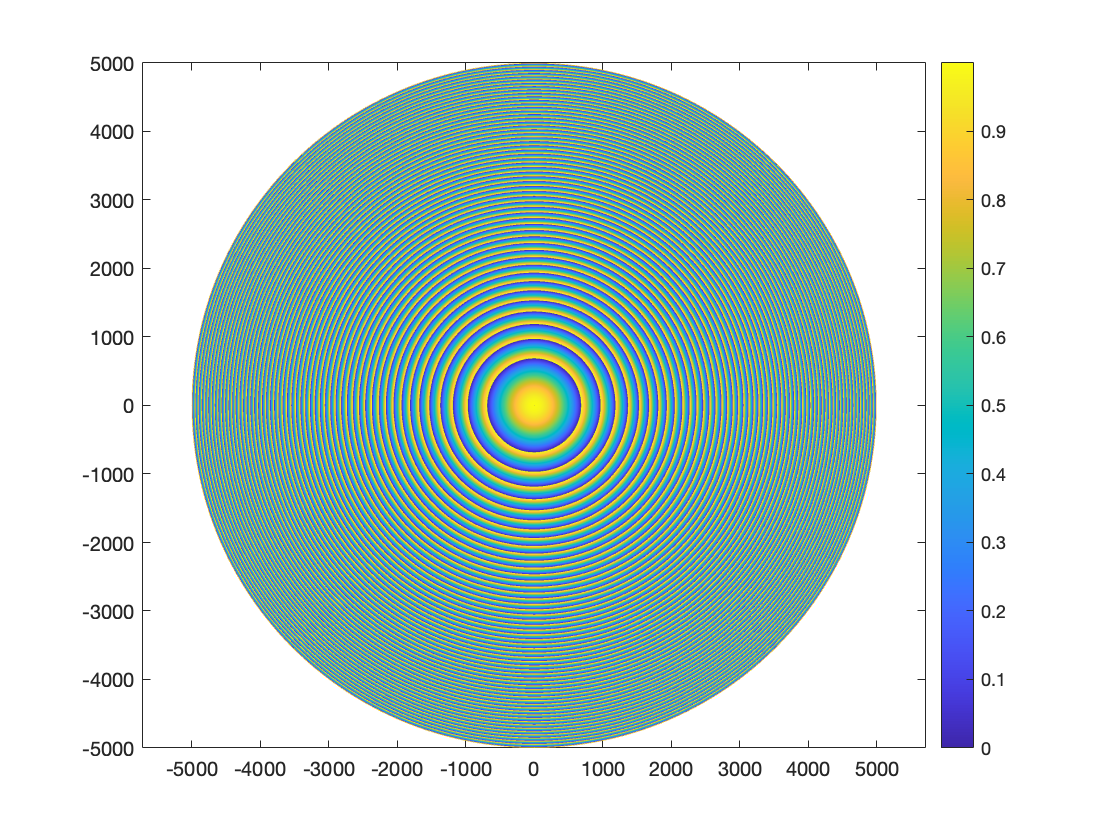

figure; pcolor(X,Y,mod(map,1)); shading flat; colorbar; axis equal

#### Task 2. Discretize the phase mask into N (6, 8, 16) levels between 0 and 1.

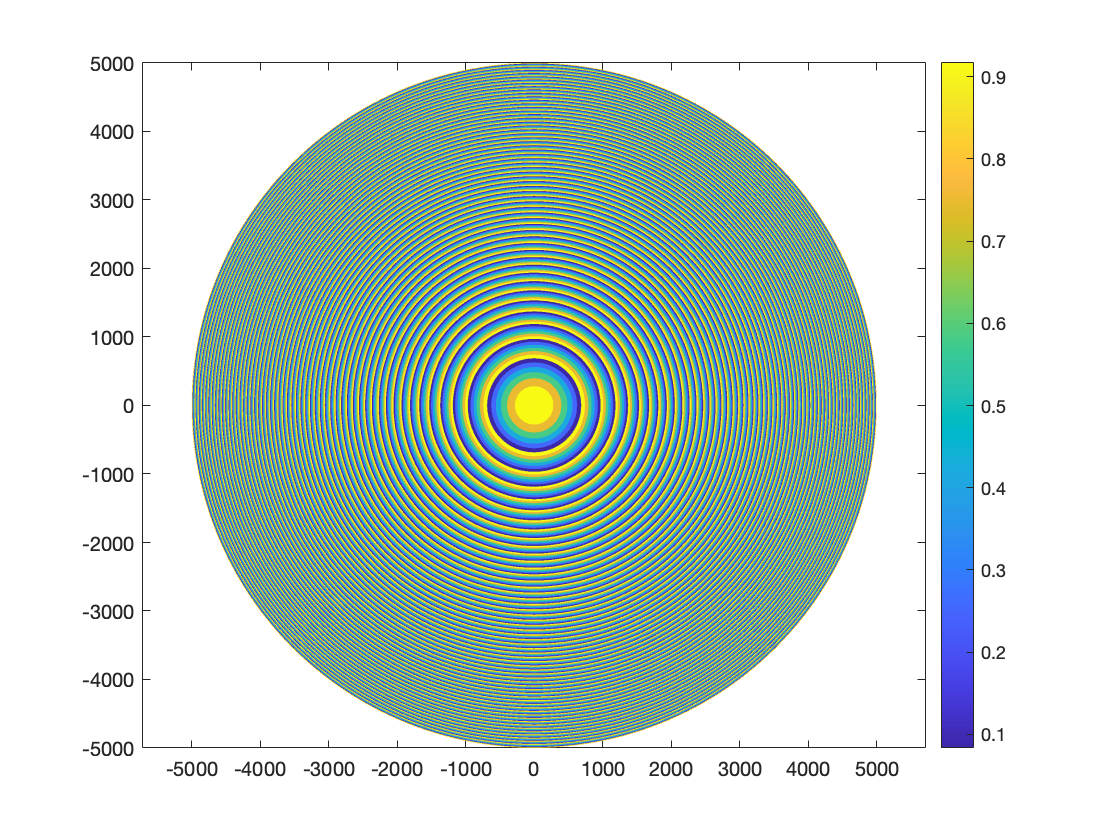

N = 6;
lvls = linspace(0,1,N+1);
lvls = lvls(2:end) - lvls(2)/2;
map = mod(map,1);
I = ~isnan(map);
[~, ilvl] = min(abs(map(I)-lvls),[],2);
map(I) = lvls(ilvl);
figure; pcolor(X,Y,map); shading flat; colorbar; axis equal